# Compare simulated outputs with the published output data

SimLog = sim('Kontoravdi2010Model');
outputLog = SimLog.yout{1}.Values;

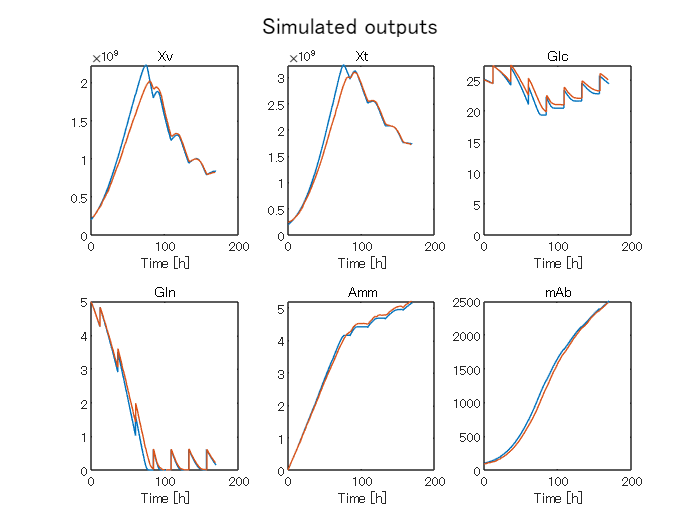

outputName = {'Xv' 'Xt' 'Glc' 'Gln' 'Amm' 'mAb'};
LogID = [2 3 4 5 7 8];

outputData = cell(6,1);
for outputIdx = 1:6
    outputData{outputIdx} = readmatrix(outputName(outputIdx) + "_FB1.csv");
end

for outputIdx = 1:6
    subplot(2,3,outputIdx)
    plot(outputLog.Time,outputLog.Data(:,LogID(outputIdx)))
    hold on
    plot(outputData{outputIdx}(:,1),outputData{outputIdx}(:,2))
    hold off
    title(outputName(outputIdx))
    xlabel('Time [h]')
    ylim([0 inf])
end
% legend({'Ours' 'Kontoravdi'})
sgtitle('Simulated outputs')